# How to use modelBorgifier

## Author: John T. Sauls, UCSD

## Reviewer: Almut Heinken, Luxembourg Centre for Systems Biomedicine

## INTRODUCTION

modelBorgifier is a package that allows users to compare and combine COBRA Toolbox ("Toolbox") style metabolic reconstructions ("models"). It is explicity designed with the notion that models from different sources use disparate naming and annotation schemes. It uses greedy string comparisons as well as network topology to identify reactions and metabolites shared and unique between models. The procedure is GUI based, and uses manual matches to train learning methods that facilitate auto-matching. 

Please read the publication (1) and accompanying manual for more information. If you find this package helpful for your work please cite:

Sauls, J. T., & Buescher, J. M. (2014). Assimilating genome-scale metabolic reconstructions with modelBorgifier. *Bioinformatics* (Oxford, England), 30(7), 1036–8. http://doi.org/10.1093/bioinformatics/btt747

Correspondance: johntsauls@gmail.com

Developed at: BRAIN Aktiengesellschaft, Microbial Production Technologies Unit, Quantitative Biology and Sequencing Platform, Darmstaeter Str. 34-36, 64673 Zwingenberg, Germany. www.brain-biotech.de

## PROCEDURE

In this tutorial we will compare the E. coli core metabolism model Ecoli_core to the Helicobacter pylori model iIT341 (2). An outline of the procedure is as follows:

1. Installation and set-up

Assuming you have succsessfully installed and tested the COBRA Toolbox for Matlab no additional configuration should be necessary. 

2. Load and verify the comparison model (Cmodel)

The comparison model (Cmodel) is any model that can be read into the COBRA Toolbox. Cmodel is "compared to" the template model (see next step). Our Cmodel will be the Ecoli_core model. 

3. Load and verify the template model (Tmodel)

The template model (Tmodel) can be simply any model, or it can be an amalgamation of models that have already been combined via modelBorgifier. Our Tmodel will be iIT341. 

4. Compare models

Every reaction in Cmodel is compared against every reaction in Tmodel and given a similarity score based on 40 parameters. This computationally expensive step is done before user-guided matching. 

5. Match models

Matching models is done with command reactionCompare. reactionCompare calls a GUI that allows the user to choose a match for a given reaction in Cmodel, and also to match the metabolites for that reaction. Comparison is facilitated by automation and proper weighting of the scoring parameters. 

6. Merge models 

Once all reactions and metabolites have been reviewed, Cmodel and Tmodel can be merged into a composite model. The composite model is the most direct way to return statistics on the similiarity between two models. 

7. Extract a model

Models merged together or into an existing composite model can be later retrieved with readCbTmodel.m. This reproduces the initial model with additional annotation information. 

8. Save work

As the composite model can be used as a template for future comparisions, save it. 

**2. Load and verify the comparision model (Cmodel)**

We first load the model we wish to compare, "Cmodel." modelBorgifier requires this model to be in a format readable by COBRA Toolbox. The verification step is specific to this package to ensure that the model has all necessary information arrays for comparison. 

i. Load the E. coli core model

We are going to use the E. coli core model located in the test/models/ directory of the Toolbox. We use this model for the tutorial because it is small and will require less time to match. 

% Load the model using the Toolbox function
Cmodel = readCbModel('ecoli_core_model.mat', ...
                     'modelDescription', 'Ecoli_core')

Cmodel =                    rxns: {95×1 cell}
                   mets: {72×1 cell}
                      S: [72×95 double]
                     lb: [95×1 double]
                     ub: [95×1 double]
                      c: [95×1 double]
               rxnNames: {95×1 cell}
             subSystems: {95×1 cell}
           rxnECNumbers: {95×1 cell}
          rxnReferences: {95×1 cell}
               rxnNotes: {95×1 cell}
                grRules: {95×1 cell}
               metNames: {72×1 cell}
            metFormulas: {72×1 cell}
              metKEGGID: {72×1 cell}
             metChEBIID: {72×1 cell}
           metPubChemID: {72×1 cell}
         metInChIString: {72×1 cell}
                  genes: {137×1 cell}
            description: 'Ecoli_core'
                  rules: {95×1 cell}
             rxnGeneMat: [95×137 double]
                      b: [72×1 double]
    rxnConfidenceScores: [95×1 double]
             metCharges: [72×1 int32]
                 osense: -1
                 c

ii. Verify the model 

modelBorgifier requires that both the comparison and template model have the proper data arrays before comparision. This function creates those arrays if they are absent and populates them when possible. You will also be prompted to keep or edit the model name ("description"). Simply press 'y' in for this tutorial. 

Note that this verify function (verifyModelMB) is different from the Toolbox function verifyModel.

% Verify model has the necessary fields required for later processing
Cmodel = verifyModelMB(Cmodel, 'keepName', 'Verbose');

Array .rxnID not in Model. Adding.
Array .rxnKEGGID not in Model. Adding.
Array .rxnSEEDID not in Model. Adding.
Array .rxnEquations not in Model. Adding.
Array .metID not in Model. Adding.
Array .metSEEDID not in Model. Adding.
Array .metCharge not in Model. Adding.
Making sure reactions are all forwards
Fixing names of metabolites and reaction
Checking if reaction IDs (.rxns) are unique.
Checking if metabolite IDs (.mets) are unique.
All metabolites have comparment designation.


**3. Load and verify the template model (Tmodel)**

We now load the template model ("Tmodel"), to which Cmodel will be compared. If you are simply comparing two models, it is arbitrary which model is the Cmodel and which is the Tmodel. However, after comparison, the two models can be merged into a composite model (from which either of the original modelds can be retrieved). This composite model can be used as the Tmodel for future comparisons. This will make future comparisons easier, as their will be more annotations information available, and allows for mutli-way model comparisons. 

i. Load the model iIT341

We will be using the *Heliobacter pylori* model packaged with the Toobox as our template model. Load it the same way as any model. If you had previous combined two models using modelBorgifier, you could simply load that composite model as your Tmodel. 

global CBTDIR
pth=which('initCobraToolbox.m');
CBTDIR = pth(1:end-(length('initCobraToolbox.m')+1));
Tmodel = readCbModel([CBTDIR filesep 'test' filesep 'models' filesep 'iIT341.xml'], ...
                     'modelDescription', 'iIT341')

The model contains 0 errors and 1 warnings.



Tmodel =                                rxns: {554×1 cell}
                               mets: {485×1 cell}
                                  S: [485×554 double]
                                 lb: [554×1 double]
                                 ub: [554×1 double]
                                  c: [554×1 double]
                           rxnNames: {554×1 cell}
                           metNames: {485×1 cell}
                        metFormulas: {485×1 cell}
                          metKEGGID: {485×1 cell}
                         metChEBIID: {485×1 cell}
                              genes: {339×1 cell}
                        description: 'iIT341'
                       modelVersion: [1×1 struct]
                              comps: {2×1 cell}
                          compNames: {2×1 cell}
      compisbigg__46__compartmentID: {2×1 cell}
                          metHMDBID: {485×1 cell}
                      metMetaNetXID: {485×1 cell}
        metisbigg__46__metaboliteID: {485

ii. Verify and convert Tmodel

Because we are just using an abritrary model as our template model, we need to verify it and convert it to a proper template model. You will be asked to confirm the name. Note that the final Tmodel, 'lb', 'ub', and 'Models are structures containing information specific to each model.

% If Tmodel is just another model, verify it as well and convert it to a
% proper format for comparison. Also make sure it carries flux. 
Tmodel = verifyModelMB(Tmodel, 'keepName', 'Verbose');

Array .rxnID not in Model. Adding.
Array .subSystems not in Model. Adding.
Array .rxnECNumbers not in Model. Adding.
Array .rxnKEGGID not in Model. Adding.
Array .rxnSEEDID not in Model. Adding.
Array .rxnEquations not in Model. Adding.
Array .rxnReferences not in Model. Adding.
Array .rxnNotes not in Model. Adding.
Array .grRules not in Model. Adding.
Array .metID not in Model. Adding.
Array .metSEEDID not in Model. Adding.
Array .metPubChemID not in Model. Adding.
Array .metInChIString not in Model. Adding.
Array .metCharge not in Model. Adding.
Making sure reactions are all forwards
Fixing names of metabolites and reaction
Checking if reaction IDs (.rxns) are unique.
Checking if metabolite IDs (.mets) are unique.
All metabolites have comparment designation.


Tmodel = buildTmodel(Tmodel);           

**4. Compare models**

compareCbModels scores all reactions in Cmodel against all reactions in Tmodel. It returns Score, a 3D matrix with size (# of reactions in Cmodel, # of reactions in Tmodel, # of scoring parameters per reaction). There are ~40 scoring parameters, such as name, E.C. number, metabolite similiarity, and network topology. The returned Cmodel and Tmodel have some appendend information, but are functionally the same as the inputs. The structure Stats contains information about the best matches per each reaction. 

Additionally, the function outputs some graphs describing the reaction scores. In particular the bottom right graph shows a reaction by reaction matrix of the scores. Lighter colors indicate a higher matching score between any two reactions. Note the transport reactions along the bottom and right of the graph. 

Adding comparison information time = 5.095442e-01.
Name match time = 2.733851e-01.
EC match time = 2.516028e-02.
Reaction KEGG ID match time = 7.361790e-04.
Reaction SEED ID match time = 5.262290e-04.
Subsystem match time = 7.466888e-02.
Metabolte number and stoich match time = 2.876957e-02.
Reaction compartment match time = 4.991152e-03.
Network topology match time = 3.724050e-01.
Met name match time = 4.133636e+01.


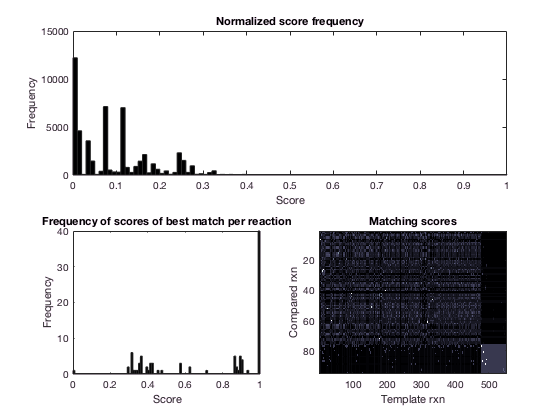

[Cmodel, Tmodel, score, Stats] = compareCbModels(Cmodel, Tmodel, 'Verbose');

**5. Match models**

reactionCompare is the major step in the comparison process. It will launch a GUI that facilitates reaction-by-reaction comparision between Cmodel and Tmodel. This section will outline the different functions of the GUI. 

Note you must run reactionCompare in the Command Window, as GUIs are not proprely rendered within the Matlab Live script. 

if ~exist('rxnList', 'var') || ~exist('metList', 'var') || ~exist('Stats', 'var')
    rxnList = [];
    metList = [];
    Stats = [];
end

% Initial comparison and matching.
% [rxnList, metList, Stats] = reactionCompare(Cmodel, Tmodel, score);

% Subsequent comparisons and matching. 
% [rxnList, metList, Stats] = reactionCompare(Cmodel, Tmodel, score, rxnList, metList, Stats);

i. Comparing similarity of reactions. Reactions from Cmodel (Ecoli_core) are displayed 1-by-1 along with the best matches from Tmodel. Information about the current reaction (gapd, reaciton #46) can be seen in the red box labeled 1. Information about the best match from Tmodel (gapd, reaction #335) is the blue box labeled 2. The score of this reaction is indicated by the blue arrow. The subsequent best reactions are to the right (Match B). 

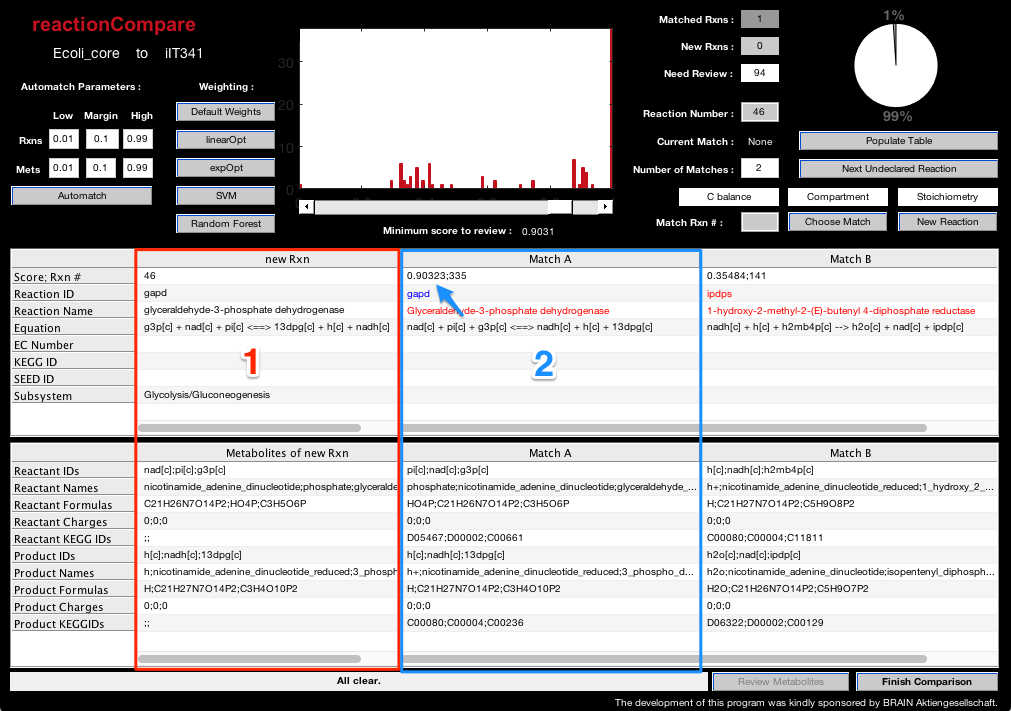

ii. Choose a matching reaction or declare a new reaction. To pair a reaction from Cmodel to a reaction in Tmodel, put the reaction number of the match into the box and press "Choose Match" (indicated by the arrow and the blue box labeled 1). If there is no appropriate match then click "New Reaction". By clicking on any of the information in the match table (such as the highlighted reaction equation under Match A), the blocks in the red box labeled 2 will indicated if this reaction matches the current reaction from Cmodel in terms of carbon balance, compartment, and metabolite stoichiometry. 

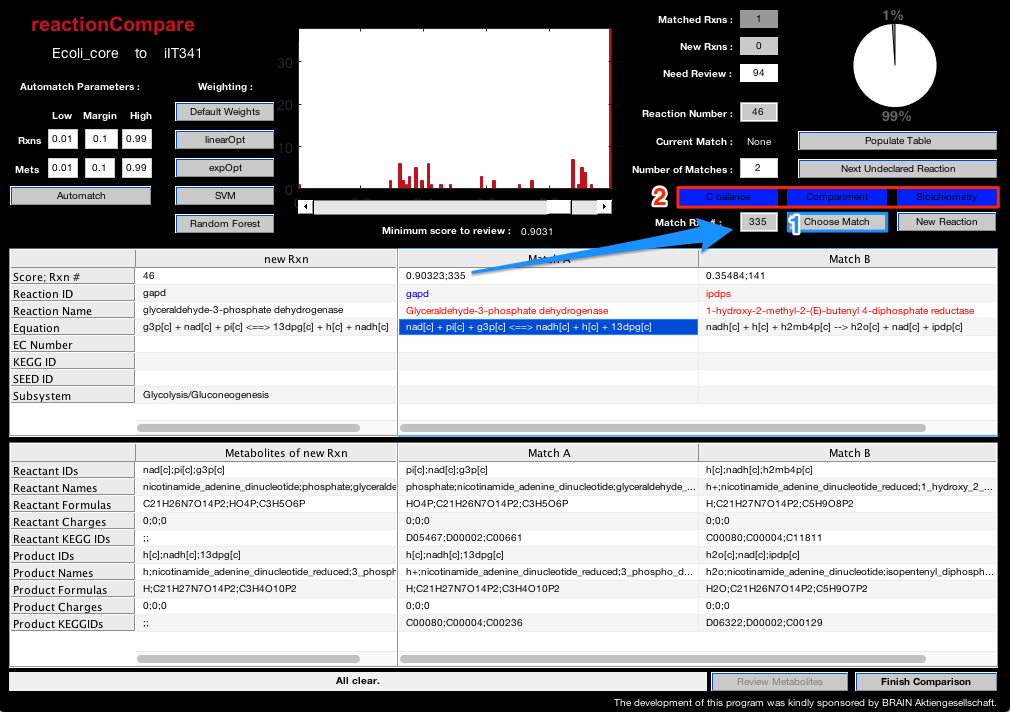

iii. Compare metabolites. When a reaction from Cmodel has been matched or declared as new, its metabolites are then reviewed in an analogous GUI. Choose the best matching metabolite from the table (Match A, Match B, ...), with the radio buttons in the red box labeled 1. You are only allowed to declare a new metabolite if the reaction itself was delcared new. After all metabolites have been reviewed (in the blue box labeled 2), you can press the button "Add Metabolite(s)" (blue arrow), and resume comparing reactions. Alternatively, you can postpone matching metabolites by pressing "Skip Matching." However, matching metabolites facilitates determining the fate of as of yet unreviewed reactions. 

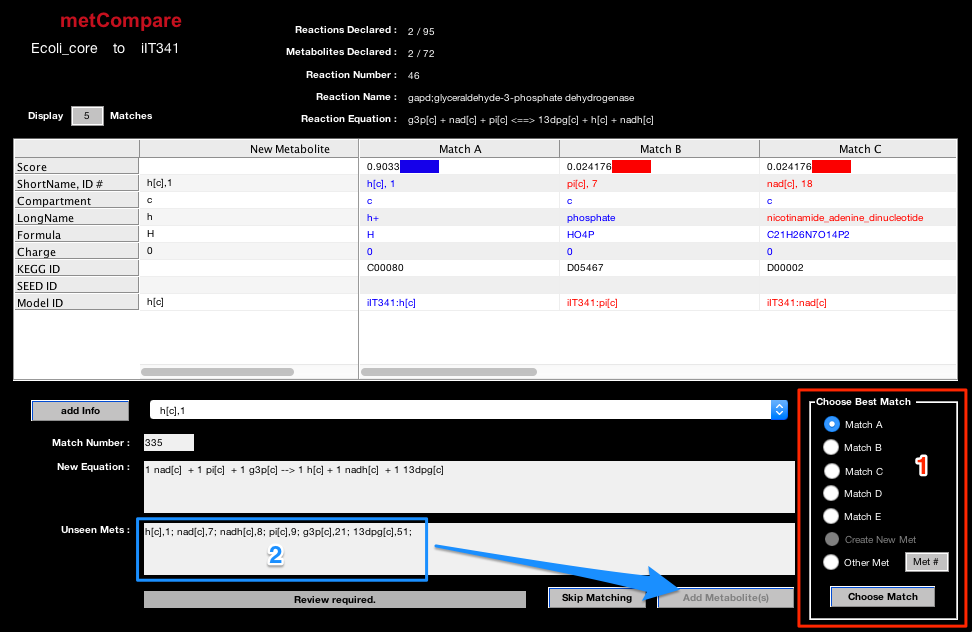

iv. Finish/pause comparison. You can quit comparison and save your work at any time by pressing "Finish Comparison" in the red box labeled 1. The number of reactions which have been reviewed, matched, or declared new is located is presented in blue box labeled 2. Finishing comparision produces two arrays, "rxnList" and "metList," which indicated to which reaction or metabolite in Tmodel matches a reaction or metabolite in Cmodel, respectively. New reactions are given a designation "-1," while new metabolites are given new metabolite numbers immediately (such numbers will be higher than the total number of metabolites in Tmodel). Unreviewed reactions and metabolites have the designation "0." 

When you resuming comparison, give rxnList and metList as arguments to reactionCompare (see above). 

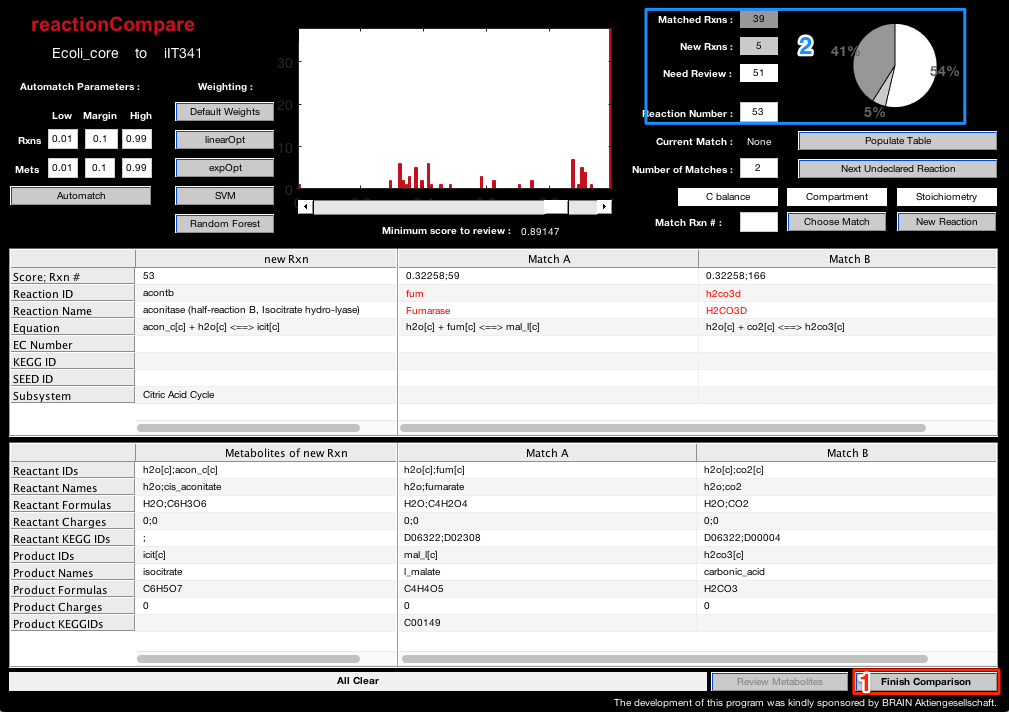

v. Review additional reacitons. You can control which reactions you review in two ways. You can review any arbitrary reaction from Cmodel by putting in the reaction number and pressing "Populate Table," indicated by the red box labeled 1. Alternatively, you can press the button "Next Undeclared Reaction," which will go to the next undeclared reaction in Cmodel with the lowest reaction number (blue box labeled 2). You can require that reactions presented by "Next Undeclared Reaction have at least one match above a give score by moving the slider indicated by the arrow. 

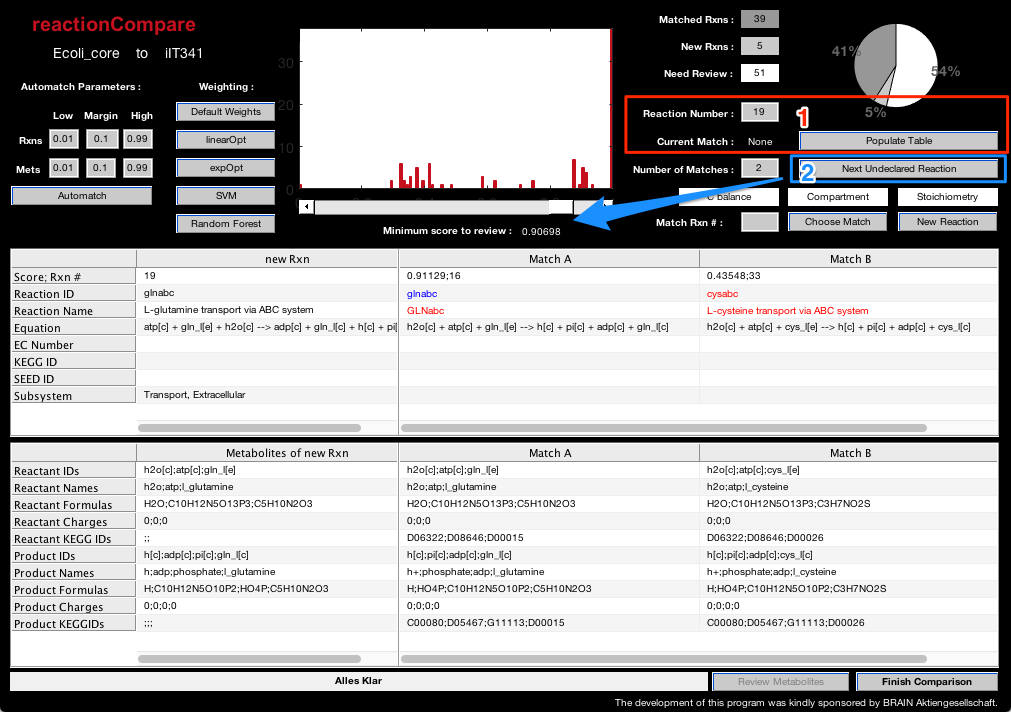

vi. Automatch reactions and metabolites. High and low scoring reactions may be safely matched or declared new, respectively. This is done with the options in the red box labeled 1. Reactions or metabolites above the score in the box "High" will be matched with their best match from Tmodel, as long as the score of the best match from Tmodel is better than the second best match by the value in "Margin." Reactions and metabolites whose matches are not above the score in "Low" will be declared as new. When a metabolite is declared as new, then all reactions in Cmodel containing that metabolite are also declared new.

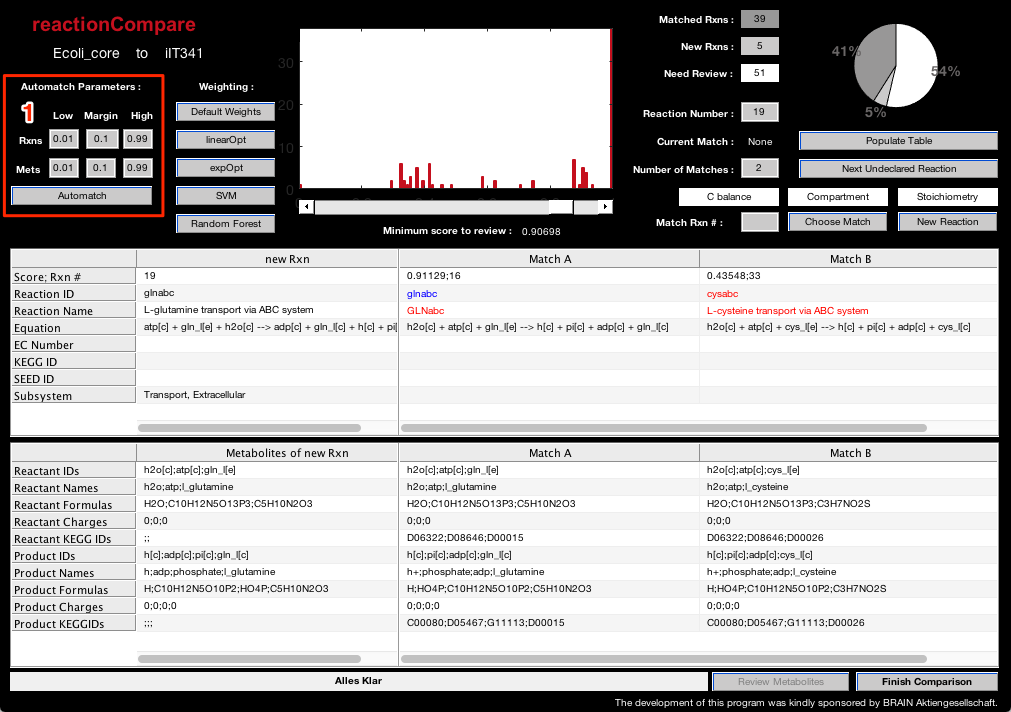

vii. Score weighting. Once you have manually compared some reactions, this information can be used to determine which scoring parameters are most informative and can be weighted accordingly. Four weighting functions/algorithms are provided in addition to the default weighting scheme (red box labeled 1). There is a linear optimization, an exponential optimization, a support vector machine (SVM) learning method, and a random forest algorithm. See the script "optimalScores.m" for more information. The image below shows the scores under SVM weighing. Automatching should be used in conjunction with score weighting to reduce manual intervention. 

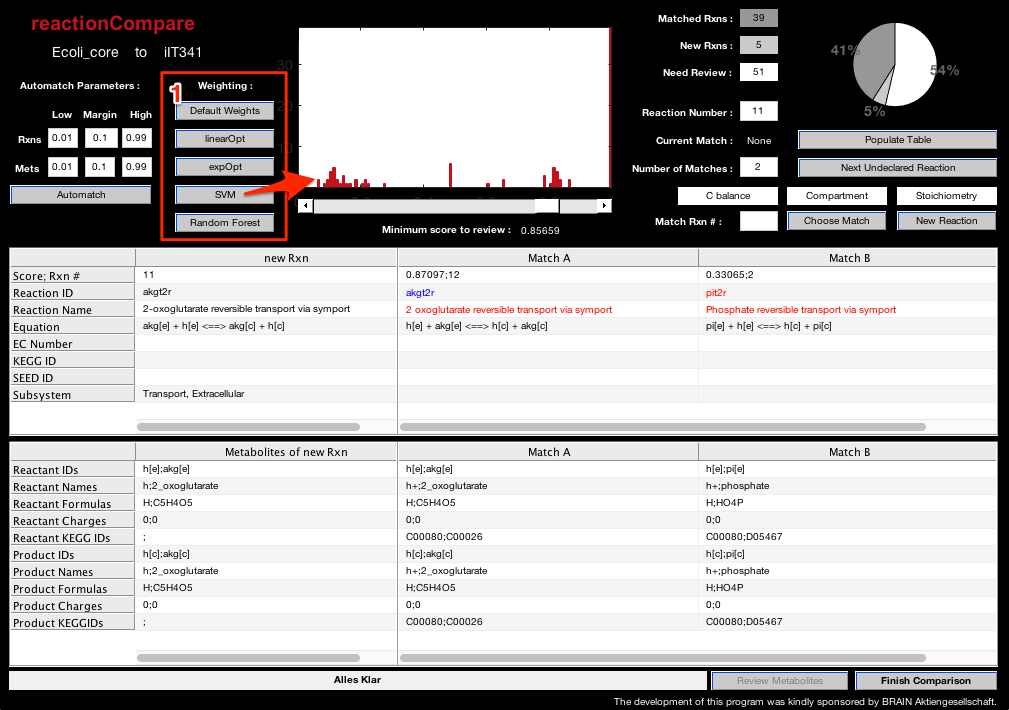

**6. Merge models**

mergeModels will combine Cmodel into Tmodel and into a composite model and return it as TmodelC. It will iteratively check the fidelity of the merging and will prompt the user if errors are found. It will also produce a copy of Cmodel which has been extracted from TmodelC (see next step).

## Merge models and test results.

if ~isempty(rxnList) && ~isempty(metList) && ~isempty(Stats)
    [TmodelC, Cspawn, Stats] = mergeModels(Cmodel, Tmodel, rxnList, metList, Stats, 'Verbose');
end

Problems within metList, resolve with GUI.
Skipped resolving, will not check fidelity of matricies.
Extracting Ecoli_core from Tmodel
Removing empty cell arrays:
rxnKEGGID
rxnSEEDID
rxnReferences
metSEEDID
metPubChemID
metInChIString
merging pyrt2(iIT341) and pyrt2r(Ecoli_core)
merging ex_gal_e(iIT341) and ex_fru_e(Ecoli_core)
merging ex_lac_l_e(iIT341) and ex_lac_d_e(Ecoli_core)


Checking if reaction IDs (.rxns) are unique.
Checking if metabolite IDs (.mets) are unique.
Extracting Ecoli_core from Tmodel
Removing empty cell arrays:
metSEEDID
metPubChemID
metInChIString


The structure Stats contains information about the number of unique and shared metabolites between the models, as well as the completeness of annotations. 

if ~isempty(rxnList) && ~isempty(metList) && ~isempty(Stats)
    % Shared reaction between the models. Values along the diagonal how many reactions in the model are unique. 
    Stats.sharedRxns
    % Shared metabolites between models, 
    Stats.sharedMets
    Stats.sharedMetsNoComp % does not consider differences in compartment. 
    
    modelNames = fieldnames(TmodelC.Models) ; 
    for iM = 2:length(modelNames)+1
        fprintf([modelNames{iM-1}, ' has ', num2str(Stats.sharedRxns{iM,iM}(1)), ' unique reactions.', ...
                       ' (', num2str(Stats.sharedRxns{iM,iM}(2)), ' percent of ', ...
                       num2str(sum(TmodelC.Models.(modelNames{iM-1}).rxns)), ' reactions).\n'])
       fprintf([modelNames{iM-1}, ' has ', num2str(Stats.sharedMets{iM,iM}(1)), ' unique metabolites.', ...
           ' (', num2str(Stats.sharedMets{iM,iM}(2)), ' percent of ', ...
           num2str(sum(TmodelC.Models.(modelNames{iM-1}).mets)), ' metabolites).\n'])
       fprintf([modelNames{iM-1}, ' has ', num2str(Stats.sharedMetsNoComp{iM,iM}(1)), ...
               ' unique metabolites when not considering compartment.\n'])
    end
    fprintf([modelNames{1}, ' shares ', num2str(Stats.sharedRxns{2, 3}(1)), ' reactions with ', ...
            modelNames{2}, '.\n'])
    fprintf([modelNames{1}, ' shares ', num2str(Stats.sharedMets{2, 3}(1)), ' metabolites with ', ...
        modelNames{2}, '.\n'])
    fprintf([modelNames{1}, ' shares ', num2str(Stats.sharedMetsNoComp{2, 3}(1)), ' metabolites with ', ...
            modelNames{2}, ' when not considering compartment.\n'])
    
end

ans =     '[Count, %]'    'in iIT341'     'in Ecoli_core'
    'iIT341'        [1×2 double]    [1×2 double]
    'Ecoli_core'    [1×2 double]    [1×2 double]


ans =     '[Count, %]'    'in iIT341'     'in Ecoli_core'
    'iIT341'        [1×2 double]    [1×2 double]
    'Ecoli_core'    [1×2 double]    [1×2 double]


ans =     '[Count, %]'    'in iIT341'     'in Ecoli_core'
    'iIT341'        [1×2 double]    [1×2 double]
    'Ecoli_core'    [1×2 double]    [1×2 double]


iIT341 has 493 unique reactions. (0.88989 percent of 554 reactions).


iIT341 has 418 unique metabolites. (0.86186 percent of 485 metabolites).


iIT341 has 362 unique metabolites when not considering compartment.


Ecoli_core has 34 unique reactions. (0.35789 percent of 95 reactions).


Ecoli_core has 5 unique metabolites. (0.069444 percent of 72 metabolites).


Ecoli_core has 4 unique metabolites when not considering compartment.


iIT341 shares 61 reactions with Ecoli_core.


iIT341 shares 67 metabolites with Ecoli_core.


iIT341 shares 50 metabolites with Ecoli_core when not considering compartment.


**7. Extract a model**

A model can be extracted from the combined model with the funtion readCbTmodel and referencing its name. Extracted models should be mathematically identical to the model that went in, but will contain additional annotation information garnered from the comparison. For example, the extracted Ecoli_core model now contains KEGG IDs for its metabolites. 

%% Extract both models 
if ~isempty(rxnList) && ~isempty(metList) && ~isempty(Stats)
    Ecoli_core = readCbTmodel('Ecoli_core', TmodelC, 'Verbose');
    iIT341 = readCbTmodel('iIT341', TmodelC, 'Verbose');
end

Extracting Ecoli_core from Tmodel
Removing empty cell arrays:
rxnKEGGID
rxnSEEDID
rxnReferences
metSEEDID
metPubChemID
metInChIString


Extracting iIT341 from Tmodel
Removing empty cell arrays:
rxnKEGGID
rxnSEEDID
rxnReferences
grRules
metSEEDID
metPubChemID
metInChIString


**8. Save work**

Finally, you should save your combined model to be used for future comparison. Subsequent comparisons become easier a Tmodel gains information. 

%     save([filesep 'Tmodel_' datestr(now,'yyyy.mm.dd') '.mat'], 'TmodelC')

## REFERENCES

- Sauls, J. T., & Buescher, J. M. (2014). Assimilating genome-scale metabolic reconstructions with modelBorgifier. *Bioinformatics* (Oxford, England), 30(7), 1036–8. [http://doi.org/10.1093/bioinformatics/btt747](http://doi.org/10.1093/bioinformatics/btt747)

- Thiele, I., Vo, T. D., Price, N. D., & Palsson, B. Ø. (2005). Expanded metabolic reconstruction of *Helicobacter pylori* (*i*IT341 GSM/GPR): an *in silico* genome-scale characterization of single- and double-deletion mutants. *Journal of Bacteriology*, *187*(16), 5818–5830. http://doi.org/10.1128/JB.187.16.5818